# Machine Learning: Programming Exercise 1

## Linear Regression

In this exercise, you will implement linear regression and get to see it work on data.

### Files needed for this exercise

- `ex1.mlx` - MATLAB Live Script that steps you through the exercise

- ex1data1.txt - Dataset for linear regression with one variable

- ex1data2.txt - Dataset for linear regression with multiple variables

- `submit.m` - Submission script that sends your solutions to our servers

- *`warmUpExercise.m` - Simple example function in MATLAB

- *`plotData.m` - Function to display the dataset

- *`computeCost.m` - Function to compute the cost of linear regression

- *`gradientDescent.m` - Function to run gradient descent

- **`computeCostMulti.m` - Cost function for multiple variables

- **`gradientDescentMulti.m` - Gradient descent for multiple variables

- **`featureNormalize.m `- Function to normalize features

- **`normalEqn.m` - Function to compute the normal equations

****indicates files you will need to complete***

*****indicates optional exercises***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex1' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir


.                       computeCostMulti.m      ex1data1.txt            gradientDescentMulti.m  plotData.m              
..                      ex1.mlx                 ex1data2.txt            lectureNotes            submit.m                
README.mlx              ex1Demo.m               featureNormalize.m      lib                     token.mat               
computeCost.m           ex1_companion.mlx       gradientDescent.m       normalEqn.m             warmUpExercise.m        



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README.mlx` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README.mlx` and have checked for an existing solution before seeking help on the discussion forums.

## 1. A simple MATLAB function

The first part of this script gives you practice with MATLAB syntax and the homework submission process. In the file `warmUpExercise.m`, you will find the outline of a MATLAB function. Modify it to return a 5 x 5 identity matrix by filling in the following code:

When you are finished, save `warmUpExercise.m`, then run the code contained in this section to call `warmUpExercise().` 

**5x5 Identity Matrix:**

warmUpExercise()

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


You should see output similar to the following:

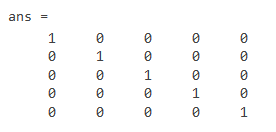

You can toggle between right-hand-side output and in-line output for printing results and displaying figures inside a Live Script by selecting the appropriate box in the upper right of the Live Editor window. 

### 1.1 Submitting Solutions

After completing a part of the exercise, you can submit your solutions for that section by running the section of code below, which calls the `submit.m` script. Your score for each section will then be displayed as output. **Enter your login and your unique submission token *****inside the command window***** when prompted. For future submissions of this exercise, you will only be asked to confirm your credentials.** Your submission token for each exercise is found in the corresponding homework assignment course page. New tokens can be generated if you are experiencing issues with your current token. You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter your login and token when prompted.*

## 2. Linear regression with one variable

In this part of this exercise, you will implement linear regression with one variable to predict profits for a food truck. Suppose you are the CEO of a restaurant franchise and are considering different cities for opening a new outlet. The chain already has trucks in various cities and you have data for profits and populations from the cities. You would like to use this data to help you select which city to expand to next.

The file `ex1data1.txt` contains the dataset for our linear regression problem. The first column is the population of a city and the second column is the profit of a food truck in that city. A negative value for profit indicates a loss. This script has already been set up to load this data for you.

### 2.1 Plotting the data

Before starting on any task, it is often useful to understand the data by visualizing it. For this dataset, you can use a scatter plot to visualize the data, since it has only two properties to plot (profit and population). Many other problems that you will encounter in real life are multi-dimensional and can't be plotted on a 2-d plot.

Run the code below to load the dataset from the data file into the variables X and y:

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);

Your job is to complete `plotData.m` to draw the plot; modify the file and fill in the following code:

Once you are finished, save `plotData.m,` and execute the code in this section which will call `plotData`. 

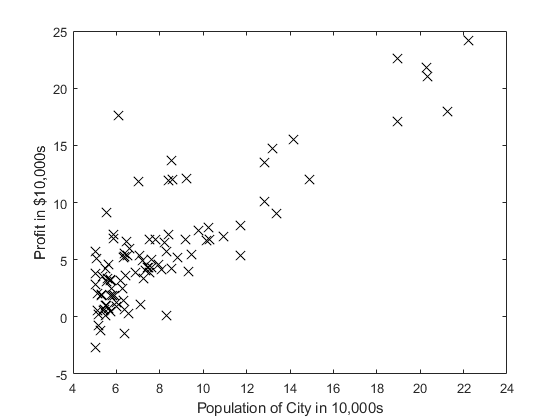

plotData(X,y)

The resulting plot should appear as in Figure 1 below:

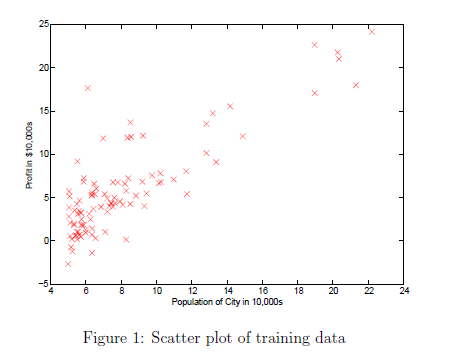

To learn more about the `plot` command, you can run the command `help plot` at the command prompt, type `plot()` inside the MATLAB Live Editor and click on the "(?)" tooltip, or you can search the [MATLAB documentation](https://www.mathworks.com/help/matlab/) for "plot". Note that to change the markers to red x's in the plot, we used the option: **'**`rx'` together with the `plot` command, i.e., 

### 2.2 Gradient Descent

In this section, you will fit the linear regression parameters to our dataset using gradient descent.

#### 2.2.1 Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^{m} {\left(h_{\theta \text{ }} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \text{ }$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


Recall that the parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\text{ }1}{m}\sum_{i=1}^{m} \text{ }\left(h_{\theta \text{ }} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \text{       }\left(\mathrm{simultaneously}\text{ }\mathrm{update}\text{ }\theta_{j\text{ }} \text{ }\mathrm{for}\text{ }\mathrm{all}\text{ }j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term ($\theta_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

#### 2.2.2 Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 

m = length(X) % number of training examples

m = 97

X = [ones(m, 1), data(:,1)]; % Add a column of ones to x (97X2)
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01;

#### 2.2.3 Computing the cost $\mathbf{J}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, you will implement a function to calculate $J\left(\theta \right)$ so you can check the convergence of your gradient descent implementation.

    Your next task is to complete the code in the file `computeCost.m`, which is a function that computes $J\left(\theta \right)$. As you are doing this, remember that the variables `X` and `y` are not scalar values, but matrices whose rows represent the examples from the training set.

    Once you have completed the function definition, run this section. The code below will call `computeCost` once using $\theta$ initialized to zeros, and you will see the cost printed to the screen. You should expect to see a cost of 32.07 for the first output below:

% Compute and display initial cost with theta all zeros
computeCost(X, y, theta) % CLEAR workout by note

J = 32.0727

ans = 32.0727

Next we call `computeCost` again, this time with non-zero `theta` values as an additional test. You should expect to see an output of 54.24 below:

% Compute and display initial cost with non-zero theta
computeCost(X, y,[-1; 2])

J = 54.2425

ans = 54.2425

If the outputs above match the expected values, you can submit your solution for assessment. If the outputs do not match or you receive an error, check your cost function for mistakes, then rerun this section once you have addressed them.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.2.4 Gradient descent

Next, you will implement gradient descent in the file `gradientDescent.m`. The loop structure has been written for you, and you only need to supply the updates to $\theta$ within each iteration.

    As you program, make sure you understand what you are trying to optimize and what is being updated. Keep in mind that the cost $J\left(\theta \right)$ is parameterized by the vector $\theta$, not $X$ and $y$. That is, we minimize the value of $J\left(\theta \right)$ by changing the values of the vector $\theta$, not by changing $X$ or $y$. Refer to the equations given earlier and to the video lectures if you are uncertain.

A good way to verify that gradient descent is working correctly is to look at the value of `J` and check that it is decreasing with each step. The starter code for `gradientDescent.m` calls `computeCost` on every iteration and prints the cost. Assuming you have implemented gradient descent and `computeCost` correctly, your value of $J\left(\theta \right)$ should never increase, and should converge to a steady value by the end of the algorithm.

    After you are finished, run this execute this section. The code below will use your final parameters to plot the linear fit. The result should look something like Figure 2 below:

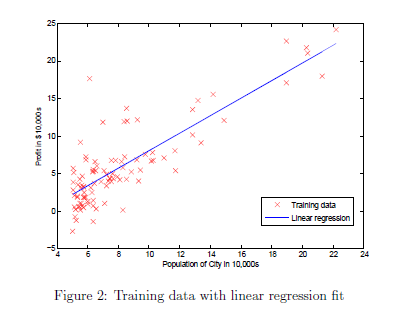    

    Your final values for $\theta$ will also be used to make predictions on profits in areas of 35,000 and 70,000 people.

% Run gradient descent:
% Compute theta
theta = gradientDescent(X, y, theta, alpha, iterations);

t1 = -566.3961

t2 = -6.3369e+03

J = 6.7372

t1 = -43.6539

t2 = -1.1322e+03

J = 5.9316

t1 = 49.1676

t2 = -206.9818

J = 5.9012

t1 = 65.5652

t2 = -42.5024

J = 5.8952

t1 = 68.3777

t2 = -13.2538

J = 5.8901

t1 = 68.7754

t2 = -8.0442

J = 5.8850

t1 = 68.7440

t2 = -7.1078

J = 5.8799

t1 = 68.6366

t2 = -6.9312

J = 5.8749

t1 = 68.5158

t2 = -6.8895

J = 5.8698

t1 = 68.3928

t2 = -6.8719

J = 5.8648

t1 = 68.2696

t2 = -6.8586

J = 5.8598

t1 = 68.1466

t2 = -6.8461

J = 5.8548

t1 = 68.0237

t2 = -6.8337

J = 5.8499

t1 = 67.9011

t2 = -6.8214

J = 5.8449

t1 = 67.7787

t2 = -6.8091

J = 5.8400

t1 = 67.6565

t2 = -6.7968

J = 5.8351

t1 = 67.5346

t2 = -6.7846

J = 5.8302

t1 = 67.4128

t2 = -6.7723

J = 5.8253

t1 = 67.2913

t2 = -6.7601

J = 5.8205

t1 = 67.1700

t2 = -6.7480

J = 5.8156

t1 = 67.0489

t2 = -6.7358

J = 5.8108

t1 = 66.9281

t2 = -6.7237

J = 5.8060

t1 = 66.8074

t2 = -6.7115

J = 5.8012

t1 = 66.6870

t2 = -6.6994

J = 5.7965

t1 = 66.5668

t2 = -6.6874

J = 5.7917

t1 = 66.4468

t2 = -6.6753

J = 5.7870

t1 = 66.3270

t2 = -6.6633

J = 5.7822

t1 = 66.2075

t2 = -6.6513

J = 5.7775

t1 = 66.0881

t2 = -6.6393

J = 5.7729

t1 = 65.9690

t2 = -6.6273

J = 5.7682

t1 = 65.8501

t2 = -6.6154

J = 5.7635

t1 = 65.7314

t2 = -6.6034

J = 5.7589

t1 = 65.6129

t2 = -6.5915

J = 5.7543

t1 = 65.4946

t2 = -6.5796

J = 5.7497

t1 = 65.3765

t2 = -6.5678

J = 5.7451

t1 = 65.2587

t2 = -6.5559

J = 5.7405

t1 = 65.1411

t2 = -6.5441

J = 5.7360

t1 = 65.0236

t2 = -6.5323

J = 5.7315

t1 = 64.9064

t2 = -6.5206

J = 5.7269

t1 = 64.7894

t2 = -6.5088

J = 5.7224

t1 = 64.6726

t2 = -6.4971

J = 5.7179

t1 = 64.5561

t2 = -6.4854

J = 5.7135

t1 = 64.4397

t2 = -6.4737

J = 5.7090

t1 = 64.3235

t2 = -6.4620

J = 5.7046

t1 = 64.2076

t2 = -6.4503

J = 5.7002

t1 = 64.0918

t2 = -6.4387

J = 5.6958

t1 = 63.9763

t2 = -6.4271

J = 5.6914

t1 = 63.8610

t2 = -6.4155

J = 5.6870

t1 = 63.7459

t2 = -6.4040

J = 5.6826

t1 = 63.6310

t2 = -6.3924

J = 5.6783

t1 = 63.5163

t2 = -6.3809

J = 5.6740

t1 = 63.4018

t2 = -6.3694

J = 5.6697

t1 = 63.2875

t2 = -6.3579

J = 5.6654

t1 = 63.1734

t2 = -6.3465

J = 5.6611

t1 = 63.0595

t2 = -6.3350

J = 5.6568

t1 = 62.9459

t2 = -6.3236

J = 5.6526

t1 = 62.8324

t2 = -6.3122

J = 5.6483

t1 = 62.7191

t2 = -6.3008

J = 5.6441

t1 = 62.6061

t2 = -6.2895

J = 5.6399

t1 = 62.4932

t2 = -6.2781

J = 5.6357

t1 = 62.3806

t2 = -6.2668

J = 5.6315

t1 = 62.2681

t2 = -6.2555

J = 5.6274

t1 = 62.1559

t2 = -6.2442

J = 5.6232

t1 = 62.0438

t2 = -6.2330

J = 5.6191

t1 = 61.9320

t2 = -6.2217

J = 5.6150

t1 = 61.8204

t2 = -6.2105

J = 5.6109

t1 = 61.7089

t2 = -6.1993

J = 5.6068

t1 = 61.5977

t2 = -6.1882

J = 5.6027

t1 = 61.4866

t2 = -6.1770

J = 5.5987

t1 = 61.3758

t2 = -6.1659

J = 5.5946

t1 = 61.2652

t2 = -6.1548

J = 5.5906

t1 = 61.1547

t2 = -6.1437

J = 5.5866

t1 = 61.0445

t2 = -6.1326

J = 5.5826

t1 = 60.9345

t2 = -6.1215

J = 5.5786

t1 = 60.8246

t2 = -6.1105

J = 5.5747

t1 = 60.7150

t2 = -6.0995

J = 5.5707

t1 = 60.6055

t2 = -6.0885

J = 5.5668

t1 = 60.4963

t2 = -6.0775

J = 5.5628

t1 = 60.3872

t2 = -6.0666

J = 5.5589

t1 = 60.2784

t2 = -6.0556

J = 5.5550

t1 = 60.1697

t2 = -6.0447

J = 5.5512

t1 = 60.0613

t2 = -6.0338

J = 5.5473

t1 = 59.9530

t2 = -6.0229

J = 5.5434

t1 = 59.8449

t2 = -6.0121

J = 5.5396

t1 = 59.7370

t2 = -6.0012

J = 5.5358

t1 = 59.6294

t2 = -5.9904

J = 5.5319

t1 = 59.5219

t2 = -5.9796

J = 5.5281

t1 = 59.4146

t2 = -5.9688

J = 5.5244

t1 = 59.3075

t2 = -5.9581

J = 5.5206

t1 = 59.2006

t2 = -5.9473

J = 5.5168

t1 = 59.0939

t2 = -5.9366

J = 5.5131

t1 = 58.9873

t2 = -5.9259

J = 5.5094

t1 = 58.8810

t2 = -5.9152

J = 5.5056

t1 = 58.7749

t2 = -5.9046

J = 5.5019

t1 = 58.6689

t2 = -5.8939

J = 5.4982

t1 = 58.5632

t2 = -5.8833

J = 5.4946

t1 = 58.4576

t2 = -5.8727

J = 5.4909

t1 = 58.3522

t2 = -5.8621

J = 5.4872

t1 = 58.2470

t2 = -5.8515

J = 5.4836

t1 = 58.1420

t2 = -5.8410

J = 5.4800

t1 = 58.0372

t2 = -5.8305

J = 5.4764

t1 = 57.9326

t2 = -5.8200

J = 5.4728

t1 = 57.8282

t2 = -5.8095

J = 5.4692

t1 = 57.7240

t2 = -5.7990

J = 5.4656

t1 = 57.6199

t2 = -5.7885

J = 5.4620

t1 = 57.5160

t2 = -5.7781

J = 5.4585

t1 = 57.4124

t2 = -5.7677

J = 5.4550

t1 = 57.3089

t2 = -5.7573

J = 5.4514

t1 = 57.2056

t2 = -5.7469

J = 5.4479

t1 = 57.1024

t2 = -5.7366

J = 5.4444

t1 = 56.9995

t2 = -5.7262

J = 5.4409

t1 = 56.8968

t2 = -5.7159

J = 5.4375

t1 = 56.7942

t2 = -5.7056

J = 5.4340

t1 = 56.6918

t2 = -5.6953

J = 5.4306

t1 = 56.5896

t2 = -5.6850

J = 5.4271

t1 = 56.4876

t2 = -5.6748

J = 5.4237

t1 = 56.3858

t2 = -5.6646

J = 5.4203

t1 = 56.2842

t2 = -5.6544

J = 5.4169

t1 = 56.1827

t2 = -5.6442

J = 5.4135

t1 = 56.0814

t2 = -5.6340

J = 5.4101

t1 = 55.9803

t2 = -5.6238

J = 5.4068

t1 = 55.8794

t2 = -5.6137

J = 5.4034

t1 = 55.7787

t2 = -5.6036

J = 5.4001

t1 = 55.6781

t2 = -5.5935

J = 5.3968

t1 = 55.5778

t2 = -5.5834

J = 5.3935

t1 = 55.4776

t2 = -5.5733

J = 5.3902

t1 = 55.3776

t2 = -5.5633

J = 5.3869

t1 = 55.2778

t2 = -5.5533

J = 5.3836

t1 = 55.1781

t2 = -5.5432

J = 5.3803

t1 = 55.0787

t2 = -5.5332

J = 5.3771

t1 = 54.9794

t2 = -5.5233

J = 5.3738

t1 = 54.8803

t2 = -5.5133

J = 5.3706

t1 = 54.7813

t2 = -5.5034

J = 5.3674

t1 = 54.6826

t2 = -5.4935

J = 5.3642

t1 = 54.5840

t2 = -5.4836

J = 5.3610

t1 = 54.4856

t2 = -5.4737

J = 5.3578

t1 = 54.3874

t2 = -5.4638

J = 5.3546

t1 = 54.2894

t2 = -5.4540

J = 5.3515

t1 = 54.1915

t2 = -5.4441

J = 5.3483

t1 = 54.0938

t2 = -5.4343

J = 5.3452

t1 = 53.9963

t2 = -5.4245

J = 5.3420

t1 = 53.8990

t2 = -5.4147

J = 5.3389

t1 = 53.8018

t2 = -5.4050

J = 5.3358

t1 = 53.7048

t2 = -5.3952

J = 5.3327

t1 = 53.6080

t2 = -5.3855

J = 5.3296

t1 = 53.5114

t2 = -5.3758

J = 5.3266

t1 = 53.4149

t2 = -5.3661

J = 5.3235

t1 = 53.3187

t2 = -5.3564

J = 5.3205

t1 = 53.2225

t2 = -5.3468

J = 5.3174

t1 = 53.1266

t2 = -5.3371

J = 5.3144

t1 = 53.0308

t2 = -5.3275

J = 5.3114

t1 = 52.9353

t2 = -5.3179

J = 5.3084

t1 = 52.8398

t2 = -5.3083

J = 5.3054

t1 = 52.7446

t2 = -5.2988

J = 5.3024

t1 = 52.6495

t2 = -5.2892

J = 5.2994

t1 = 52.5546

t2 = -5.2797

J = 5.2965

t1 = 52.4599

t2 = -5.2702

J = 5.2935

t1 = 52.3653

t2 = -5.2607

J = 5.2906

t1 = 52.2709

t2 = -5.2512

J = 5.2876

t1 = 52.1767

t2 = -5.2417

J = 5.2847

t1 = 52.0826

t2 = -5.2323

J = 5.2818

t1 = 51.9887

t2 = -5.2228

J = 5.2789

t1 = 51.8950

t2 = -5.2134

J = 5.2760

t1 = 51.8015

t2 = -5.2040

J = 5.2731

t1 = 51.7081

t2 = -5.1946

J = 5.2703

t1 = 51.6149

t2 = -5.1853

J = 5.2674

t1 = 51.5219

t2 = -5.1759

J = 5.2646

t1 = 51.4290

t2 = -5.1666

J = 5.2617

t1 = 51.3363

t2 = -5.1573

J = 5.2589

t1 = 51.2437

t2 = -5.1480

J = 5.2561

t1 = 51.1514

t2 = -5.1387

J = 5.2533

t1 = 51.0592

t2 = -5.1294

J = 5.2505

t1 = 50.9671

t2 = -5.1202

J = 5.2477

t1 = 50.8753

t2 = -5.1110

J = 5.2449

t1 = 50.7835

t2 = -5.1018

J = 5.2422

t1 = 50.6920

t2 = -5.0926

J = 5.2394

t1 = 50.6006

t2 = -5.0834

J = 5.2367

t1 = 50.5094

t2 = -5.0742

J = 5.2339

t1 = 50.4184

t2 = -5.0651

J = 5.2312

t1 = 50.3275

t2 = -5.0559

J = 5.2285

t1 = 50.2368

t2 = -5.0468

J = 5.2258

t1 = 50.1462

t2 = -5.0377

J = 5.2231

t1 = 50.0558

t2 = -5.0286

J = 5.2204

t1 = 49.9656

t2 = -5.0196

J = 5.2177

t1 = 49.8755

t2 = -5.0105

J = 5.2150

t1 = 49.7856

t2 = -5.0015

J = 5.2124

t1 = 49.6959

t2 = -4.9925

J = 5.2097

t1 = 49.6063

t2 = -4.9835

J = 5.2071

t1 = 49.5169

t2 = -4.9745

J = 5.2045

t1 = 49.4276

t2 = -4.9655

J = 5.2018

t1 = 49.3385

t2 = -4.9566

J = 5.1992

t1 = 49.2496

t2 = -4.9477

J = 5.1966

t1 = 49.1608

t2 = -4.9387

J = 5.1940

t1 = 49.0722

t2 = -4.9298

J = 5.1915

t1 = 48.9837

t2 = -4.9209

J = 5.1889

t1 = 48.8954

t2 = -4.9121

J = 5.1863

t1 = 48.8073

t2 = -4.9032

J = 5.1838

t1 = 48.7193

t2 = -4.8944

J = 5.1812

t1 = 48.6315

t2 = -4.8856

J = 5.1787

t1 = 48.5438

t2 = -4.8768

J = 5.1762

t1 = 48.4563

t2 = -4.8680

J = 5.1736

t1 = 48.3690

t2 = -4.8592

J = 5.1711

t1 = 48.2818

t2 = -4.8504

J = 5.1686

t1 = 48.1947

t2 = -4.8417

J = 5.1661

t1 = 48.1079

t2 = -4.8330

J = 5.1637

t1 = 48.0211

t2 = -4.8242

J = 5.1612

t1 = 47.9346

t2 = -4.8155

J = 5.1587

t1 = 47.8482

t2 = -4.8069

J = 5.1563

t1 = 47.7619

t2 = -4.7982

J = 5.1538

t1 = 47.6758

t2 = -4.7896

J = 5.1514

t1 = 47.5899

t2 = -4.7809

J = 5.1489

t1 = 47.5041

t2 = -4.7723

J = 5.1465

t1 = 47.4185

t2 = -4.7637

J = 5.1441

t1 = 47.3330

t2 = -4.7551

J = 5.1417

t1 = 47.2477

t2 = -4.7465

J = 5.1393

t1 = 47.1625

t2 = -4.7380

J = 5.1369

t1 = 47.0775

t2 = -4.7294

J = 5.1346

t1 = 46.9926

t2 = -4.7209

J = 5.1322

t1 = 46.9079

t2 = -4.7124

J = 5.1298

t1 = 46.8234

t2 = -4.7039

J = 5.1275

t1 = 46.7390

t2 = -4.6954

J = 5.1251

t1 = 46.6547

t2 = -4.6870

J = 5.1228

t1 = 46.5706

t2 = -4.6785

J = 5.1205

t1 = 46.4867

t2 = -4.6701

J = 5.1181

t1 = 46.4029

t2 = -4.6617

J = 5.1158

t1 = 46.3192

t2 = -4.6533

J = 5.1135

t1 = 46.2357

t2 = -4.6449

J = 5.1112

t1 = 46.1524

t2 = -4.6365

J = 5.1090

t1 = 46.0692

t2 = -4.6281

J = 5.1067

t1 = 45.9861

t2 = -4.6198

J = 5.1044

t1 = 45.9033

t2 = -4.6115

J = 5.1022

t1 = 45.8205

t2 = -4.6032

J = 5.0999

t1 = 45.7379

t2 = -4.5949

J = 5.0977

t1 = 45.6555

t2 = -4.5866

J = 5.0954

t1 = 45.5732

t2 = -4.5783

J = 5.0932

t1 = 45.4910

t2 = -4.5701

J = 5.0910

t1 = 45.4090

t2 = -4.5618

J = 5.0888

t1 = 45.3272

t2 = -4.5536

J = 5.0866

t1 = 45.2455

t2 = -4.5454

J = 5.0844

t1 = 45.1639

t2 = -4.5372

J = 5.0822

t1 = 45.0825

t2 = -4.5290

J = 5.0800

t1 = 45.0012

t2 = -4.5209

J = 5.0778

t1 = 44.9201

t2 = -4.5127

J = 5.0757

t1 = 44.8391

t2 = -4.5046

J = 5.0735

t1 = 44.7583

t2 = -4.4965

J = 5.0714

t1 = 44.6776

t2 = -4.4884

J = 5.0692

t1 = 44.5971

t2 = -4.4803

J = 5.0671

t1 = 44.5167

t2 = -4.4722

J = 5.0650

t1 = 44.4364

t2 = -4.4641

J = 5.0628

t1 = 44.3563

t2 = -4.4561

J = 5.0607

t1 = 44.2764

t2 = -4.4480

J = 5.0586

t1 = 44.1966

t2 = -4.4400

J = 5.0565

t1 = 44.1169

t2 = -4.4320

J = 5.0544

t1 = 44.0374

t2 = -4.4240

J = 5.0524

t1 = 43.9580

t2 = -4.4161

J = 5.0503

t1 = 43.8788

t2 = -4.4081

J = 5.0482

t1 = 43.7997

t2 = -4.4002

J = 5.0462

t1 = 43.7207

t2 = -4.3922

J = 5.0441

t1 = 43.6419

t2 = -4.3843

J = 5.0421

t1 = 43.5632

t2 = -4.3764

J = 5.0400

t1 = 43.4847

t2 = -4.3685

J = 5.0380

t1 = 43.4063

t2 = -4.3606

J = 5.0360

t1 = 43.3281

t2 = -4.3528

J = 5.0340

t1 = 43.2500

t2 = -4.3449

J = 5.0320

t1 = 43.1720

t2 = -4.3371

J = 5.0300

t1 = 43.0942

t2 = -4.3293

J = 5.0280

t1 = 43.0165

t2 = -4.3215

J = 5.0260

t1 = 42.9390

t2 = -4.3137

J = 5.0240

t1 = 42.8616

t2 = -4.3059

J = 5.0220

t1 = 42.7843

t2 = -4.2981

J = 5.0201

t1 = 42.7072

t2 = -4.2904

J = 5.0181

t1 = 42.6302

t2 = -4.2827

J = 5.0162

t1 = 42.5534

t2 = -4.2749

J = 5.0142

t1 = 42.4766

t2 = -4.2672

J = 5.0123

t1 = 42.4001

t2 = -4.2595

J = 5.0104

t1 = 42.3236

t2 = -4.2519

J = 5.0085

t1 = 42.2474

t2 = -4.2442

J = 5.0065

t1 = 42.1712

t2 = -4.2366

J = 5.0046

t1 = 42.0952

t2 = -4.2289

J = 5.0027

t1 = 42.0193

t2 = -4.2213

J = 5.0008

t1 = 41.9436

t2 = -4.2137

J = 4.9989

t1 = 41.8679

t2 = -4.2061

J = 4.9971

t1 = 41.7925

t2 = -4.1985

J = 4.9952

t1 = 41.7171

t2 = -4.1909

J = 4.9933

t1 = 41.6419

t2 = -4.1834

J = 4.9915

t1 = 41.5669

t2 = -4.1758

J = 4.9896

t1 = 41.4920

t2 = -4.1683

J = 4.9878

t1 = 41.4172

t2 = -4.1608

J = 4.9859

t1 = 41.3425

t2 = -4.1533

J = 4.9841

t1 = 41.2680

t2 = -4.1458

J = 4.9823

t1 = 41.1936

t2 = -4.1383

J = 4.9805

t1 = 41.1193

t2 = -4.1309

J = 4.9786

t1 = 41.0452

t2 = -4.1234

J = 4.9768

t1 = 40.9712

t2 = -4.1160

J = 4.9750

t1 = 40.8974

t2 = -4.1086

J = 4.9732

t1 = 40.8236

t2 = -4.1012

J = 4.9714

t1 = 40.7501

t2 = -4.0938

J = 4.9697

t1 = 40.6766

t2 = -4.0864

J = 4.9679

t1 = 40.6033

t2 = -4.0790

J = 4.9661

t1 = 40.5301

t2 = -4.0717

J = 4.9644

t1 = 40.4570

t2 = -4.0643

J = 4.9626

t1 = 40.3841

t2 = -4.0570

J = 4.9609

t1 = 40.3113

t2 = -4.0497

J = 4.9591

t1 = 40.2386

t2 = -4.0424

J = 4.9574

t1 = 40.1661

t2 = -4.0351

J = 4.9556

t1 = 40.0937

t2 = -4.0278

J = 4.9539

t1 = 40.0214

t2 = -4.0206

J = 4.9522

t1 = 39.9493

t2 = -4.0133

J = 4.9505

t1 = 39.8773

t2 = -4.0061

J = 4.9488

t1 = 39.8054

t2 = -3.9989

J = 4.9471

t1 = 39.7336

t2 = -3.9917

J = 4.9454

t1 = 39.6620

t2 = -3.9845

J = 4.9437

t1 = 39.5905

t2 = -3.9773

J = 4.9420

t1 = 39.5192

t2 = -3.9701

J = 4.9404

t1 = 39.4479

t2 = -3.9630

J = 4.9387

t1 = 39.3768

t2 = -3.9558

J = 4.9370

t1 = 39.3058

t2 = -3.9487

J = 4.9354

t1 = 39.2350

t2 = -3.9416

J = 4.9337

t1 = 39.1643

t2 = -3.9345

J = 4.9321

t1 = 39.0937

t2 = -3.9274

J = 4.9304

t1 = 39.0232

t2 = -3.9203

J = 4.9288

t1 = 38.9528

t2 = -3.9132

J = 4.9272

t1 = 38.8826

t2 = -3.9062

J = 4.9255

t1 = 38.8125

t2 = -3.8991

J = 4.9239

t1 = 38.7426

t2 = -3.8921

J = 4.9223

t1 = 38.6727

t2 = -3.8851

J = 4.9207

t1 = 38.6030

t2 = -3.8781

J = 4.9191

t1 = 38.5334

t2 = -3.8711

J = 4.9175

t1 = 38.4640

t2 = -3.8641

J = 4.9159

t1 = 38.3946

t2 = -3.8572

J = 4.9144

t1 = 38.3254

t2 = -3.8502

J = 4.9128

t1 = 38.2563

t2 = -3.8433

J = 4.9112

t1 = 38.1874

t2 = -3.8363

J = 4.9096

t1 = 38.1185

t2 = -3.8294

J = 4.9081

t1 = 38.0498

t2 = -3.8225

J = 4.9065

t1 = 37.9812

t2 = -3.8156

J = 4.9050

t1 = 37.9128

t2 = -3.8088

J = 4.9034

t1 = 37.8444

t2 = -3.8019

J = 4.9019

t1 = 37.7762

t2 = -3.7950

J = 4.9004

t1 = 37.7081

t2 = -3.7882

J = 4.8989

t1 = 37.6402

t2 = -3.7814

J = 4.8973

t1 = 37.5723

t2 = -3.7745

J = 4.8958

t1 = 37.5046

t2 = -3.7677

J = 4.8943

t1 = 37.4370

t2 = -3.7609

J = 4.8928

t1 = 37.3695

t2 = -3.7542

J = 4.8913

t1 = 37.3021

t2 = -3.7474

J = 4.8898

t1 = 37.2349

t2 = -3.7406

J = 4.8883

t1 = 37.1678

t2 = -3.7339

J = 4.8868

t1 = 37.1008

t2 = -3.7272

J = 4.8854

t1 = 37.0339

t2 = -3.7205

J = 4.8839

t1 = 36.9671

t2 = -3.7137

J = 4.8824

t1 = 36.9005

t2 = -3.7071

J = 4.8810

t1 = 36.8340

t2 = -3.7004

J = 4.8795

t1 = 36.7676

t2 = -3.6937

J = 4.8781

t1 = 36.7013

t2 = -3.6870

J = 4.8766

t1 = 36.6351

t2 = -3.6804

J = 4.8752

t1 = 36.5691

t2 = -3.6738

J = 4.8738

t1 = 36.5032

t2 = -3.6671

J = 4.8723

t1 = 36.4374

t2 = -3.6605

J = 4.8709

t1 = 36.3717

t2 = -3.6539

J = 4.8695

t1 = 36.3061

t2 = -3.6473

J = 4.8681

t1 = 36.2407

t2 = -3.6408

J = 4.8667

t1 = 36.1754

t2 = -3.6342

J = 4.8653

t1 = 36.1102

t2 = -3.6277

J = 4.8639

t1 = 36.0451

t2 = -3.6211

J = 4.8625

t1 = 35.9801

t2 = -3.6146

J = 4.8611

t1 = 35.9152

t2 = -3.6081

J = 4.8597

t1 = 35.8505

t2 = -3.6016

J = 4.8583

t1 = 35.7859

t2 = -3.5951

J = 4.8569

t1 = 35.7214

t2 = -3.5886

J = 4.8556

t1 = 35.6570

t2 = -3.5821

J = 4.8542

t1 = 35.5927

t2 = -3.5757

J = 4.8528

t1 = 35.5285

t2 = -3.5692

J = 4.8515

t1 = 35.4645

t2 = -3.5628

J = 4.8501

t1 = 35.4006

t2 = -3.5564

J = 4.8488

t1 = 35.3368

t2 = -3.5500

J = 4.8475

t1 = 35.2731

t2 = -3.5436

J = 4.8461

t1 = 35.2095

t2 = -3.5372

J = 4.8448

t1 = 35.1460

t2 = -3.5308

J = 4.8435

t1 = 35.0827

t2 = -3.5244

J = 4.8422

t1 = 35.0194

t2 = -3.5181

J = 4.8408

t1 = 34.9563

t2 = -3.5117

J = 4.8395

t1 = 34.8933

t2 = -3.5054

J = 4.8382

t1 = 34.8304

t2 = -3.4991

J = 4.8369

t1 = 34.7676

t2 = -3.4928

J = 4.8356

t1 = 34.7049

t2 = -3.4865

J = 4.8343

t1 = 34.6424

t2 = -3.4802

J = 4.8330

t1 = 34.5799

t2 = -3.4739

J = 4.8318

t1 = 34.5176

t2 = -3.4677

J = 4.8305

t1 = 34.4554

t2 = -3.4614

J = 4.8292

t1 = 34.3933

t2 = -3.4552

J = 4.8279

t1 = 34.3313

t2 = -3.4489

J = 4.8267

t1 = 34.2694

t2 = -3.4427

J = 4.8254

t1 = 34.2076

t2 = -3.4365

J = 4.8242

t1 = 34.1459

t2 = -3.4303

J = 4.8229

t1 = 34.0844

t2 = -3.4241

J = 4.8217

t1 = 34.0229

t2 = -3.4180

J = 4.8204

t1 = 33.9616

t2 = -3.4118

J = 4.8192

t1 = 33.9004

t2 = -3.4057

J = 4.8180

t1 = 33.8393

t2 = -3.3995

J = 4.8167

t1 = 33.7783

t2 = -3.3934

J = 4.8155

t1 = 33.7174

t2 = -3.3873

J = 4.8143

t1 = 33.6566

t2 = -3.3812

J = 4.8131

t1 = 33.5959

t2 = -3.3751

J = 4.8119

t1 = 33.5354

t2 = -3.3690

J = 4.8107

t1 = 33.4749

t2 = -3.3629

J = 4.8094

t1 = 33.4146

t2 = -3.3569

J = 4.8083

t1 = 33.3544

t2 = -3.3508

J = 4.8071

t1 = 33.2942

t2 = -3.3448

J = 4.8059

t1 = 33.2342

t2 = -3.3387

J = 4.8047

t1 = 33.1743

t2 = -3.3327

J = 4.8035

t1 = 33.1145

t2 = -3.3267

J = 4.8023

t1 = 33.0548

t2 = -3.3207

J = 4.8012

t1 = 32.9952

t2 = -3.3147

J = 4.8000

t1 = 32.9358

t2 = -3.3088

J = 4.7988

t1 = 32.8764

t2 = -3.3028

J = 4.7977

t1 = 32.8171

t2 = -3.2968

J = 4.7965

t1 = 32.7580

t2 = -3.2909

J = 4.7954

t1 = 32.6989

t2 = -3.2850

J = 4.7942

t1 = 32.6400

t2 = -3.2790

J = 4.7931

t1 = 32.5811

t2 = -3.2731

J = 4.7919

t1 = 32.5224

t2 = -3.2672

J = 4.7908

t1 = 32.4638

t2 = -3.2613

J = 4.7897

t1 = 32.4053

t2 = -3.2555

J = 4.7885

t1 = 32.3469

t2 = -3.2496

J = 4.7874

t1 = 32.2885

t2 = -3.2437

J = 4.7863

t1 = 32.2303

t2 = -3.2379

J = 4.7852

t1 = 32.1722

t2 = -3.2321

J = 4.7841

t1 = 32.1143

t2 = -3.2262

J = 4.7830

t1 = 32.0564

t2 = -3.2204

J = 4.7819

t1 = 31.9986

t2 = -3.2146

J = 4.7808

t1 = 31.9409

t2 = -3.2088

J = 4.7797

t1 = 31.8833

t2 = -3.2030

J = 4.7786

t1 = 31.8258

t2 = -3.1973

J = 4.7775

t1 = 31.7685

t2 = -3.1915

J = 4.7764

t1 = 31.7112

t2 = -3.1857

J = 4.7753

t1 = 31.6541

t2 = -3.1800

J = 4.7743

t1 = 31.5970

t2 = -3.1743

J = 4.7732

t1 = 31.5400

t2 = -3.1685

J = 4.7721

t1 = 31.4832

t2 = -3.1628

J = 4.7711

t1 = 31.4264

t2 = -3.1571

J = 4.7700

t1 = 31.3698

t2 = -3.1514

J = 4.7689

t1 = 31.3132

t2 = -3.1458

J = 4.7679

t1 = 31.2568

t2 = -3.1401

J = 4.7668

t1 = 31.2004

t2 = -3.1344

J = 4.7658

t1 = 31.1442

t2 = -3.1288

J = 4.7648

t1 = 31.0881

t2 = -3.1231

J = 4.7637

t1 = 31.0320

t2 = -3.1175

J = 4.7627

t1 = 30.9761

t2 = -3.1119

J = 4.7617

t1 = 30.9202

t2 = -3.1063

J = 4.7606

t1 = 30.8645

t2 = -3.1007

J = 4.7596

t1 = 30.8089

t2 = -3.0951

J = 4.7586

t1 = 30.7533

t2 = -3.0895

J = 4.7576

t1 = 30.6979

t2 = -3.0839

J = 4.7566

t1 = 30.6426

t2 = -3.0784

J = 4.7556

t1 = 30.5873

t2 = -3.0728

J = 4.7546

t1 = 30.5322

t2 = -3.0673

J = 4.7536

t1 = 30.4772

t2 = -3.0618

J = 4.7526

t1 = 30.4222

t2 = -3.0562

J = 4.7516

t1 = 30.3674

t2 = -3.0507

J = 4.7506

t1 = 30.3126

t2 = -3.0452

J = 4.7496

t1 = 30.2580

t2 = -3.0397

J = 4.7486

t1 = 30.2035

t2 = -3.0343

J = 4.7476

t1 = 30.1490

t2 = -3.0288

J = 4.7467

t1 = 30.0947

t2 = -3.0233

J = 4.7457

t1 = 30.0404

t2 = -3.0179

J = 4.7447

t1 = 29.9863

t2 = -3.0124

J = 4.7438

t1 = 29.9322

t2 = -3.0070

J = 4.7428

t1 = 29.8783

t2 = -3.0016

J = 4.7418

t1 = 29.8244

t2 = -2.9962

J = 4.7409

t1 = 29.7706

t2 = -2.9908

J = 4.7399

t1 = 29.7170

t2 = -2.9854

J = 4.7390

t1 = 29.6634

t2 = -2.9800

J = 4.7380

t1 = 29.6099

t2 = -2.9746

J = 4.7371

t1 = 29.5566

t2 = -2.9693

J = 4.7362

t1 = 29.5033

t2 = -2.9639

J = 4.7352

t1 = 29.4501

t2 = -2.9586

J = 4.7343

t1 = 29.3970

t2 = -2.9532

J = 4.7334

t1 = 29.3440

t2 = -2.9479

J = 4.7325

t1 = 29.2911

t2 = -2.9426

J = 4.7315

t1 = 29.2383

t2 = -2.9373

J = 4.7306

t1 = 29.1856

t2 = -2.9320

J = 4.7297

t1 = 29.1330

t2 = -2.9267

J = 4.7288

t1 = 29.0805

t2 = -2.9215

J = 4.7279

t1 = 29.0281

t2 = -2.9162

J = 4.7270

t1 = 28.9757

t2 = -2.9109

J = 4.7261

t1 = 28.9235

t2 = -2.9057

J = 4.7252

t1 = 28.8714

t2 = -2.9004

J = 4.7243

t1 = 28.8193

t2 = -2.8952

J = 4.7234

t1 = 28.7674

t2 = -2.8900

J = 4.7225

t1 = 28.7155

t2 = -2.8848

J = 4.7216

t1 = 28.6638

t2 = -2.8796

J = 4.7207

t1 = 28.6121

t2 = -2.8744

J = 4.7199

t1 = 28.5605

t2 = -2.8692

J = 4.7190

t1 = 28.5090

t2 = -2.8640

J = 4.7181

t1 = 28.4576

t2 = -2.8589

J = 4.7173

t1 = 28.4064

t2 = -2.8537

J = 4.7164

t1 = 28.3551

t2 = -2.8486

J = 4.7155

t1 = 28.3040

t2 = -2.8434

J = 4.7147

t1 = 28.2530

t2 = -2.8383

J = 4.7138

t1 = 28.2021

t2 = -2.8332

J = 4.7130

t1 = 28.1512

t2 = -2.8281

J = 4.7121

t1 = 28.1005

t2 = -2.8230

J = 4.7113

t1 = 28.0498

t2 = -2.8179

J = 4.7104

t1 = 27.9993

t2 = -2.8128

J = 4.7096

t1 = 27.9488

t2 = -2.8078

J = 4.7087

t1 = 27.8984

t2 = -2.8027

J = 4.7079

t1 = 27.8481

t2 = -2.7976

J = 4.7071

t1 = 27.7979

t2 = -2.7926

J = 4.7062

t1 = 27.7478

t2 = -2.7876

J = 4.7054

t1 = 27.6978

t2 = -2.7825

J = 4.7046

t1 = 27.6479

t2 = -2.7775

J = 4.7038

t1 = 27.5981

t2 = -2.7725

J = 4.7030

t1 = 27.5483

t2 = -2.7675

J = 4.7021

t1 = 27.4986

t2 = -2.7625

J = 4.7013

t1 = 27.4491

t2 = -2.7576

J = 4.7005

t1 = 27.3996

t2 = -2.7526

J = 4.6997

t1 = 27.3502

t2 = -2.7476

J = 4.6989

t1 = 27.3009

t2 = -2.7427

J = 4.6981

t1 = 27.2517

t2 = -2.7377

J = 4.6973

t1 = 27.2026

t2 = -2.7328

J = 4.6965

t1 = 27.1535

t2 = -2.7279

J = 4.6957

t1 = 27.1046

t2 = -2.7229

J = 4.6949

t1 = 27.0557

t2 = -2.7180

J = 4.6942

t1 = 27.0070

t2 = -2.7131

J = 4.6934

t1 = 26.9583

t2 = -2.7083

J = 4.6926

t1 = 26.9097

t2 = -2.7034

J = 4.6918

t1 = 26.8612

t2 = -2.6985

J = 4.6910

t1 = 26.8128

t2 = -2.6936

J = 4.6903

t1 = 26.7644

t2 = -2.6888

J = 4.6895

t1 = 26.7162

t2 = -2.6839

J = 4.6887

t1 = 26.6680

t2 = -2.6791

J = 4.6880

t1 = 26.6199

t2 = -2.6743

J = 4.6872

t1 = 26.5720

t2 = -2.6694

J = 4.6865

t1 = 26.5241

t2 = -2.6646

J = 4.6857

t1 = 26.4762

t2 = -2.6598

J = 4.6850

t1 = 26.4285

t2 = -2.6550

J = 4.6842

t1 = 26.3809

t2 = -2.6502

J = 4.6835

t1 = 26.3333

t2 = -2.6455

J = 4.6827

t1 = 26.2859

t2 = -2.6407

J = 4.6820

t1 = 26.2385

t2 = -2.6359

J = 4.6812

t1 = 26.1912

t2 = -2.6312

J = 4.6805

t1 = 26.1440

t2 = -2.6264

J = 4.6798

t1 = 26.0968

t2 = -2.6217

J = 4.6790

t1 = 26.0498

t2 = -2.6170

J = 4.6783

t1 = 26.0028

t2 = -2.6123

J = 4.6776

t1 = 25.9560

t2 = -2.6076

J = 4.6769

t1 = 25.9092

t2 = -2.6029

J = 4.6761

t1 = 25.8625

t2 = -2.5982

J = 4.6754

t1 = 25.8159

t2 = -2.5935

J = 4.6747

t1 = 25.7693

t2 = -2.5888

J = 4.6740

t1 = 25.7229

t2 = -2.5841

J = 4.6733

t1 = 25.6765

t2 = -2.5795

J = 4.6726

t1 = 25.6302

t2 = -2.5748

J = 4.6719

t1 = 25.5840

t2 = -2.5702

J = 4.6712

t1 = 25.5379

t2 = -2.5656

J = 4.6705

t1 = 25.4919

t2 = -2.5609

J = 4.6698

t1 = 25.4459

t2 = -2.5563

J = 4.6691

t1 = 25.4000

t2 = -2.5517

J = 4.6684

t1 = 25.3543

t2 = -2.5471

J = 4.6677

t1 = 25.3086

t2 = -2.5425

J = 4.6670

t1 = 25.2629

t2 = -2.5379

J = 4.6663

t1 = 25.2174

t2 = -2.5334

J = 4.6656

t1 = 25.1719

t2 = -2.5288

J = 4.6650

t1 = 25.1266

t2 = -2.5242

J = 4.6643

t1 = 25.0813

t2 = -2.5197

J = 4.6636

t1 = 25.0361

t2 = -2.5151

J = 4.6629

t1 = 24.9909

t2 = -2.5106

J = 4.6623

t1 = 24.9459

t2 = -2.5061

J = 4.6616

t1 = 24.9009

t2 = -2.5016

J = 4.6609

t1 = 24.8560

t2 = -2.4971

J = 4.6603

t1 = 24.8112

t2 = -2.4926

J = 4.6596

t1 = 24.7665

t2 = -2.4881

J = 4.6590

t1 = 24.7219

t2 = -2.4836

J = 4.6583

t1 = 24.6773

t2 = -2.4791

J = 4.6577

t1 = 24.6328

t2 = -2.4746

J = 4.6570

t1 = 24.5884

t2 = -2.4702

J = 4.6564

t1 = 24.5441

t2 = -2.4657

J = 4.6557

t1 = 24.4998

t2 = -2.4613

J = 4.6551

t1 = 24.4557

t2 = -2.4568

J = 4.6544

t1 = 24.4116

t2 = -2.4524

J = 4.6538

t1 = 24.3676

t2 = -2.4480

J = 4.6531

t1 = 24.3237

t2 = -2.4436

J = 4.6525

t1 = 24.2798

t2 = -2.4392

J = 4.6519

t1 = 24.2360

t2 = -2.4348

J = 4.6513

t1 = 24.1924

t2 = -2.4304

J = 4.6506

t1 = 24.1488

t2 = -2.4260

J = 4.6500

t1 = 24.1052

t2 = -2.4216

J = 4.6494

t1 = 24.0618

t2 = -2.4173

J = 4.6488

t1 = 24.0184

t2 = -2.4129

J = 4.6481

t1 = 23.9751

t2 = -2.4086

J = 4.6475

t1 = 23.9319

t2 = -2.4042

J = 4.6469

t1 = 23.8887

t2 = -2.3999

J = 4.6463

t1 = 23.8457

t2 = -2.3956

J = 4.6457

t1 = 23.8027

t2 = -2.3912

J = 4.6451

t1 = 23.7598

t2 = -2.3869

J = 4.6445

t1 = 23.7170

t2 = -2.3826

J = 4.6439

t1 = 23.6742

t2 = -2.3783

J = 4.6433

t1 = 23.6315

t2 = -2.3740

J = 4.6427

t1 = 23.5889

t2 = -2.3698

J = 4.6421

t1 = 23.5464

t2 = -2.3655

J = 4.6415

t1 = 23.5040

t2 = -2.3612

J = 4.6409

t1 = 23.4616

t2 = -2.3570

J = 4.6403

t1 = 23.4193

t2 = -2.3527

J = 4.6397

t1 = 23.3771

t2 = -2.3485

J = 4.6391

t1 = 23.3350

t2 = -2.3442

J = 4.6385

t1 = 23.2929

t2 = -2.3400

J = 4.6380

t1 = 23.2509

t2 = -2.3358

J = 4.6374

t1 = 23.2090

t2 = -2.3316

J = 4.6368

t1 = 23.1672

t2 = -2.3274

J = 4.6362

t1 = 23.1254

t2 = -2.3232

J = 4.6356

t1 = 23.0837

t2 = -2.3190

J = 4.6351

t1 = 23.0421

t2 = -2.3148

J = 4.6345

t1 = 23.0006

t2 = -2.3107

J = 4.6339

t1 = 22.9591

t2 = -2.3065

J = 4.6334

t1 = 22.9177

t2 = -2.3023

J = 4.6328

t1 = 22.8764

t2 = -2.2982

J = 4.6322

t1 = 22.8352

t2 = -2.2940

J = 4.6317

t1 = 22.7940

t2 = -2.2899

J = 4.6311

t1 = 22.7529

t2 = -2.2858

J = 4.6306

t1 = 22.7119

t2 = -2.2817

J = 4.6300

t1 = 22.6710

t2 = -2.2775

J = 4.6295

t1 = 22.6301

t2 = -2.2734

J = 4.6289

t1 = 22.5893

t2 = -2.2693

J = 4.6284

t1 = 22.5486

t2 = -2.2652

J = 4.6278

t1 = 22.5079

t2 = -2.2612

J = 4.6273

t1 = 22.4674

t2 = -2.2571

J = 4.6267

t1 = 22.4269

t2 = -2.2530

J = 4.6262

t1 = 22.3864

t2 = -2.2490

J = 4.6257

t1 = 22.3461

t2 = -2.2449

J = 4.6251

t1 = 22.3058

t2 = -2.2409

J = 4.6246

t1 = 22.2656

t2 = -2.2368

J = 4.6241

t1 = 22.2255

t2 = -2.2328

J = 4.6235

t1 = 22.1854

t2 = -2.2288

J = 4.6230

t1 = 22.1454

t2 = -2.2247

J = 4.6225

t1 = 22.1055

t2 = -2.2207

J = 4.6220

t1 = 22.0656

t2 = -2.2167

J = 4.6214

t1 = 22.0259

t2 = -2.2127

J = 4.6209

t1 = 21.9862

t2 = -2.2087

J = 4.6204

t1 = 21.9465

t2 = -2.2048

J = 4.6199

t1 = 21.9070

t2 = -2.2008

J = 4.6194

t1 = 21.8675

t2 = -2.1968

J = 4.6189

t1 = 21.8281

t2 = -2.1929

J = 4.6183

t1 = 21.7887

t2 = -2.1889

J = 4.6178

t1 = 21.7494

t2 = -2.1850

J = 4.6173

t1 = 21.7102

t2 = -2.1810

J = 4.6168

t1 = 21.6711

t2 = -2.1771

J = 4.6163

t1 = 21.6320

t2 = -2.1732

J = 4.6158

t1 = 21.5930

t2 = -2.1693

J = 4.6153

t1 = 21.5541

t2 = -2.1653

J = 4.6148

t1 = 21.5153

t2 = -2.1614

J = 4.6143

t1 = 21.4765

t2 = -2.1575

J = 4.6138

t1 = 21.4378

t2 = -2.1537

J = 4.6133

t1 = 21.3991

t2 = -2.1498

J = 4.6128

t1 = 21.3605

t2 = -2.1459

J = 4.6123

t1 = 21.3220

t2 = -2.1420

J = 4.6119

t1 = 21.2836

t2 = -2.1382

J = 4.6114

t1 = 21.2452

t2 = -2.1343

J = 4.6109

t1 = 21.2069

t2 = -2.1305

J = 4.6104

t1 = 21.1687

t2 = -2.1266

J = 4.6099

t1 = 21.1306

t2 = -2.1228

J = 4.6094

t1 = 21.0925

t2 = -2.1190

J = 4.6090

t1 = 21.0544

t2 = -2.1151

J = 4.6085

t1 = 21.0165

t2 = -2.1113

J = 4.6080


% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-') % we wnat to set new y value 
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure

% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);
predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

    Note the way that the lines above use matrix multiplication, rather than explicit summation or looping, to calculate the predictions. This is an example of *code vectorization* in MATLAB. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.3 Debugging

Here are some things to keep in mind as you implement gradient descent: 

- MATLAB array indices start from one, not zero. If you're storing $\theta_0$ and $\theta_1$ in a vector called `theta`, the values will be `theta(1)` and `theta(2)`.

- If you are seeing many errors at runtime, inspect your matrix operations to make sure that you're adding and multiplying matrices of compatible dimensions. Printing the dimensions of variables with the `size` command will help you debug.

- By default, MATLAB interprets math operators to be matrix operators. This is a common source of size incompatibility errors. If you don't want matrix multiplication, you need to add the "dot" notation to specify this to MATLAB. For example, `A*B` does a matrix multiply, while `A.*B` does an element-wise multiplication.

### 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, you will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values. You will not need to code anything new for this part, but you should understand how the code you have written already is creating these images.

    In the next step, there is code set up to calculate $J(\theta)$ over a grid of values using the `computeCost` function that you wrote. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);  % linspace(X1, X2) generates a row vector of 100 linearly from -10 to 10
                                       %equally spaced points between X1 and X2.
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals)); % (100X100)

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];     % (t = [1,1],[1,2],..,[1,100],[2,1],[2,2],..,[100,100])
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

    After the code above is executed, you will have a 2-D array of $J(\theta)$ values. The code below will then use these values to produce surface and contour plots of $J(\theta)$ using the `surf` and `contour` commands. Run the code in this section now. The resulting plots should look something like the figure below.

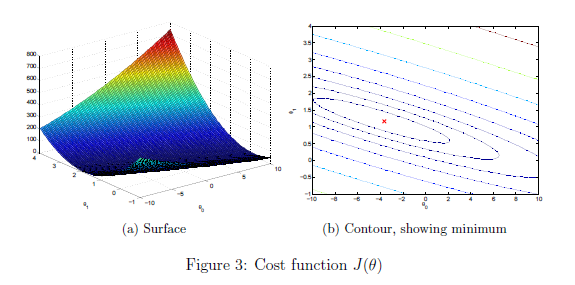

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

    The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

## Optional Exercises:

If you have successfully completed the material above, congratulations! You now understand linear regression and should able to start using it on your own datasets. For the rest of this programming exercise, we have included the following optional exercises. These exercises will help you gain a deeper understanding of the material, and if you are able to do so, we encourage you to complete them as well.

## 3. Linear regression with multiple variables

In this part, you will implement linear regression with multiple variables to predict the prices of houses. Suppose you are selling your house and you want to know what a good market price would be. One way to do this is to first collect information on recent houses sold and make a model of housing prices.

    The file `ex1data2.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house. Run this section now to preview the data.

% Load Data
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');  % CLEAR BY WORKOUT IN MATLAB PROMPT

The remainder of this script has been set up to help you step through this exercise.

### 3.1 Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

    Your task here is to complete the code in `featureNormalize.m` to:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

The standard deviation is a way of measuring how much variation there is in the range of values of a particular feature (most data points will lie within $\pm 2$ standard deviations of the mean); this is an alternative to taking the range of values (*max - min*). In MATLAB, you can use the `std` function to compute the standard deviation. For example, inside `featureNormalize.m`, the quantity `X(:,1)` contains all the values of $x_1$ (house sizes) in the training set, so `std(X(:,1))` computes the standard deviation of the house sizes. At the time that `featureNormalize.m` is called, the extra column of 1's corresponding to $x_0 = 1$ has not yet been added to `X` (see the code below for details).

    You will do this for all the features and your code should work with datasets of all sizes (any number of features / examples). Note that each column of the matrix `X` corresponds to one feature. When you are finished with `featureNormailize.m`, run this section to normailze the features of the housing dataset.

% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);

**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the prices of houses we have not seen before. Given a new `x` value (living room area and number of bedrooms), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% Add intercept term to X
X = [ones(m, 1) X];

### 3.2 Gradient Descent

Previously, you implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

    You should complete the code in `computeCostMulti.m` and `gradientDescentMulti``.m `to implement the cost function and gradient descent for linear regression *with multiple variables*. If your code in the previous part (single variable) already supports multiple variables, you can use it here too.

Make sure your code supports any number of features and is well-vectorized. You can use the command `size(X,2)` to find out how many features are present in the dataset.

    We have provided you with the following starter code below that runs gradient descent with a particular learning rate (`alpha`). Your task is to first make sure that your functions `computeCost` and `gradientDescent` already work with this starter code and support multiple variables.  

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\text{ }\left(x^{\left(1\right)} \right)}^T -\\
{-\text{ }\left(x^{\left(2\right)} \right)}^T -\\
\vdots \text{ }\\
{-\text{ }\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \text{           }\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \text{ }\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


The vectorized version is efficient when you're working with numerical computing tools like MATLAB. If you are an expert with matrix operations, you can prove to yourself that the two forms are equivalent.

% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

Finally, you should complete and run the code below to predict the price of a 1650 sq-ft, 3 br house using the value of `theta` obtained above. 

**Hint:** At prediction, make sure you do the same feature normalization. Recall that the first column of `X` is all ones. Thus, it does not need to be normalized.

% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================

price = 0; % Enter your price formula here
price_Norm = ([1650 3] - mu)./sigma
price_Norm = [ones(1,1) price_Norm]
predict = price_Norm * theta
% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', predict);

#### **3.2.1 Optional (ungraded) exercise: Selecting learning rates**

In this part of the exercise, you will get to try out dierent learning rates for the dataset and find a learning rate that converges quickly. You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will call your `gradientDescent` function and run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

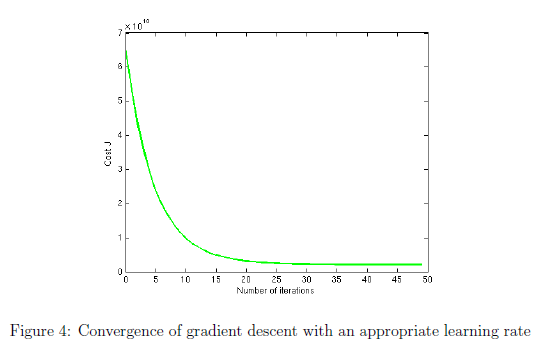

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \text{ }\infty$.

**MATLAB Tip:** To compare how different learning learning rates affect convergence, it's helpful to plot `J` for several learning rates on the same figure. In MATLAB, this can be done by performing gradient descent multiple times with a `hold on` command between plots. Make sure to use the `hold off` command when you are done plotting in that figure. Concretely, if you've tried three different values of `alpha` (you should probably try more values than this) and stored the costs in `J1`, `J2` and `J3`, you can use the following commands to plot them on the same figure:

    The final arguments `'b'`,`'r'`, and `'k``'` specify different colors for the plots. If desired, you can use this technique and adapt the code below to plot multiple convergence histories in the same plot. 

% Run gradient descent:
% Choose some alpha value
alpha = 0.1;
num_iters = 200;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[~, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

    Using the best learning rate that you found, run the section of code below, which will run gradient descent until convergence to find the final values of $\theta$. Next, use this value of $\theta$ to predict the price of a house with 1650 square feet and 3 bedrooms. You will use value later to check your implementation of the normal equations. Don't forget to normalize your features when you make this prediction!

% Run gradient descent
% Replace the value of alpha below best alpha value you found above
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f',theta(1),theta(2))

% Estimate the price of a 1650 sq-ft, 3 br house. You can use the same
% code you entered ealier to predict the price
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

price_Norm = ([1650 3] - mu)./sigma

price_Norm = [ones(1,1) price_Norm]

price = price_Norm * theta
% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

### 3.3 Normal Equations

In the lecture videos, you learned that the closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

    Complete the code in `normalEqn.m` to use the formula above to calculate $\theta$, then run the code in this section. Remember that while you don't need to scale your features, we still need to add a column of 1's to the `X` matrix to have an intercept term ($\theta_0$) . Note that the code below will add the column of 1's to `X` for you.

% Solve with normal equations:
% Load Data
data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f', theta(1),theta(2));

**Optional (ungraded) exercise: **Now, once you have found $\theta$ using this method, use it to make a price prediction for a 1650-square-foot house with 3 bedrooms. You should find that gives the same predicted price as the value you obtained using the model fit with gradient descent (in Section 3.2.1).

% Estimate the price of a 1650 sq-ft, 3 br house. 
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price forumla here
price_Norm = ([1650 3] - mu)./sigma

price_Norm = [ones(1,1) price_Norm]

price = price_Norm * theta

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using normal equations):\n $%f', price);     

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

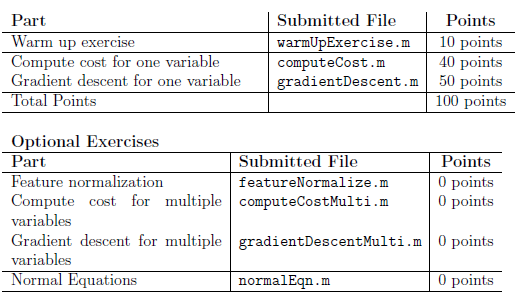

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.